# Where are the earthquakes?

There were a lot of earthquakes in February 2018. Where were they, and how strong were they?

These earthquakes are rated using the [Richter magnitude scale](https://en.wikipedia.org/wiki/Richter_magnitude_scale) which is determined from the logarithm of the amplitude of waves recorded by seismographs. 

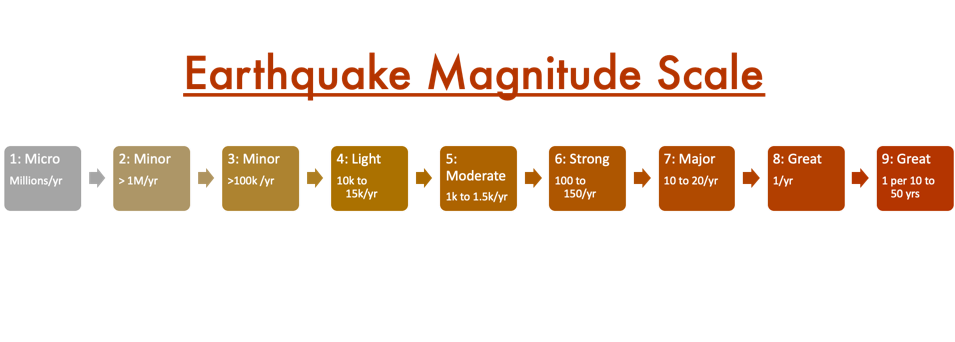

The formula is: $M_L =\log_{10} A-\log_{10} A_0 \left(\delta \right)=\log_{10} \left\lbrack A/A_0 \left(\delta \right)\right\rbrack$. [Earthquake Data Credit](https://earthquake.usgs.gov/fdsnws/event/1/): U.S. Geological Survey; Department of the Interior/USGS

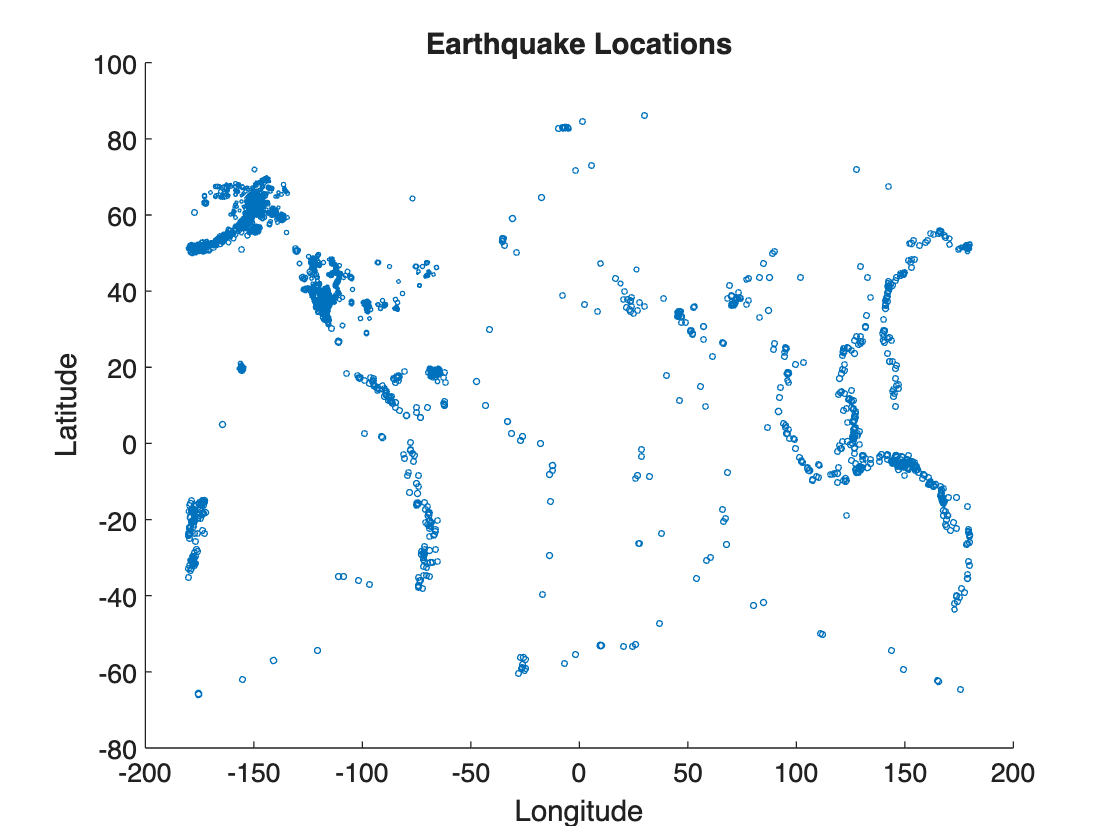

load EarthquakesFebruary2018 quakes
plotquakes(quakes);

## Earthquakes around the world

Let's take a look at where earthquakes occur and how strong they are. Filter out the smallest earthquakes.

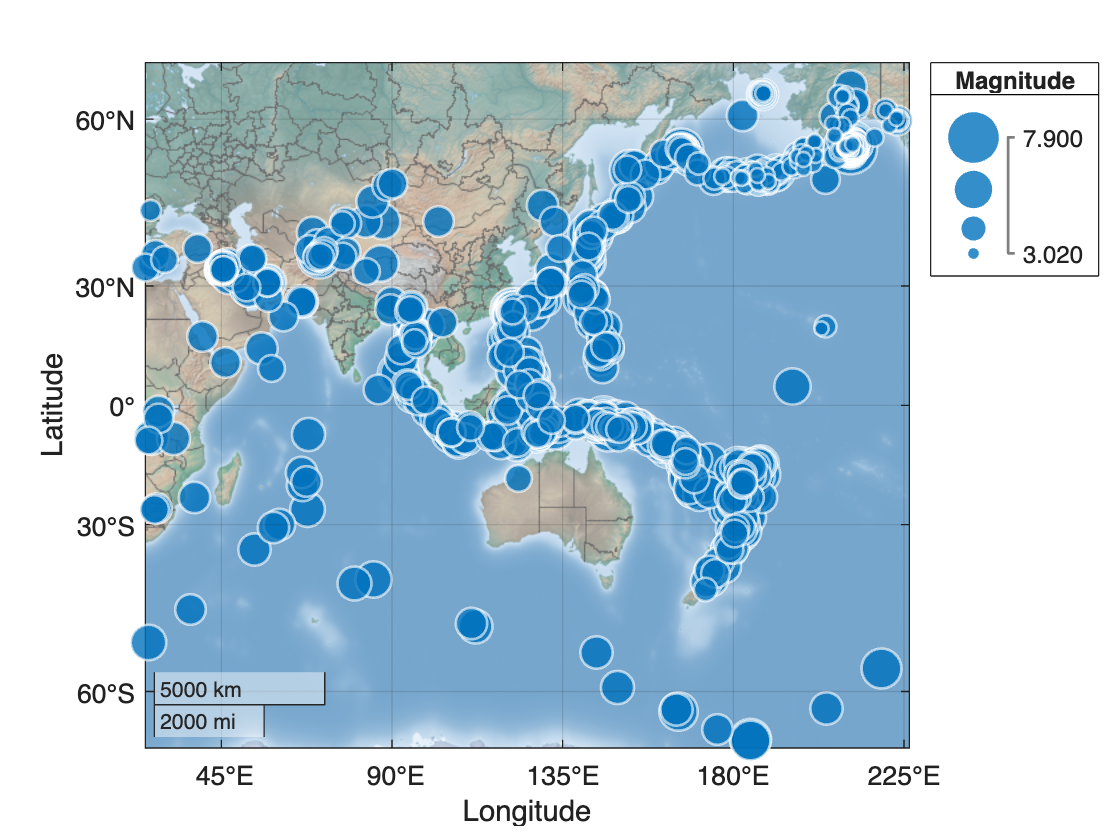

minmagnitude = 3;
theseQuakes = quakes(quakes.Magnitude > minmagnitude,:);
geobubble(theseQuakes,"Latitude","Longitude","SizeVariable","Magnitude",...
    "Basemap","colorterrain");